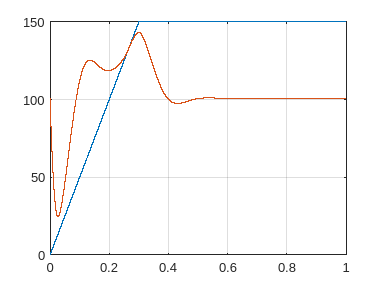

clc; clear all; close all;

rho = 850; % kg/m^3
beta = 900*10^6; % N/m^2
Cd = 0.55;
Ad = 15/10^6; % m^2
d = 63/1000; % m
A = pi/4*d^2; % m^2
m = 3200; % kg
g = 9.81; % m/s^2

V2min = 2000/10^6; % m^3

y = 0;
F = m*g;
p2 = F/A;
yDot = 0;
p1max = 150*10^5; % Pa
tr = 0.3; % s

simTime = 1; % s
dt = 10^-5; % s
t = 0; % s
idx = 1;

while(t <= simTime)
    % Calculations
    if(t <= tr)
        p1 = t/tr * p1max;
    else
        p1 = p1max;
    end

    if(y < 0)
        y = 0;
    end

    V2 = V2min + A*y;

    Q = Cd*Ad*sign(p1-p2)*sqrt(2/rho*abs(p1-p2));
    p2Dot = beta/V2*(Q-A*yDot);

    % F = ma
    F = m*g;
    yDotDot = (A*p2-F)/m; 

    % Logging
    t_plt(idx) = t;
    p1plt(idx) = p1/10^5;
    p2plt(idx) = p2/10^5;

    % Time integration
    yDot = yDot + yDotDot * dt;
    y = y + yDot * dt;
    p2 = p2 + p2Dot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, p1plt)
hold on
plot(t_plt, p2plt)
grid